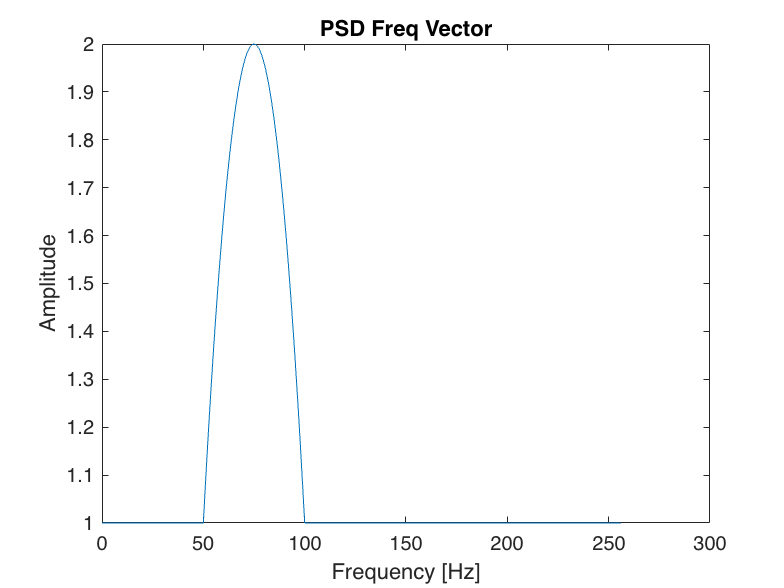

%Testing GLRT PSO
%Luis Mario Bres Castro

addpath ../Func&data
addpath '/Users/luisbres/Desktop/Spring 2022/StatisticalMethods/SDMBIGDAT19-master/CODES'



%Define parameters
A=[10,3,3]; %parameters of QC signal
snr=10;
nruns=8;
nite=1000;
%Search Ranges
a1=[1 180];
a2=[1 10];
a3=[1 10];


%Generate Data
samplFreq = 512;%hz
nSamples = 512;
dataLen = nSamples/samplFreq;
% time samples vector
timeVec = (0:(nSamples-1))/samplFreq;

noisePSD = @(f) (f>=50 & f<=100).*(f-50).*(100-f)/625 + 1;
% set up frequency
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))*(1/dataLen); % vector of positive frequencies

% psd vector
psdVec = noisePSD(posFreq);
figure
plot(posFreq,psdVec);
title('PSD Freq Vector')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

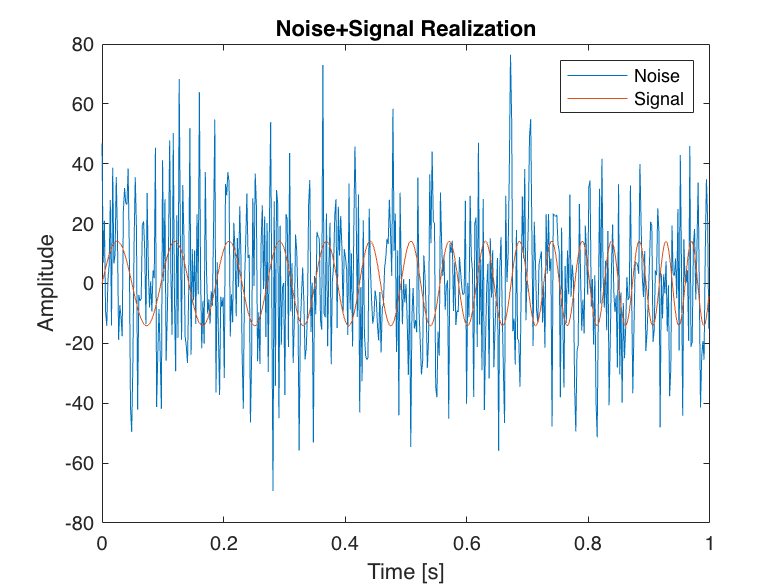

% generate colored noise
filtOrdr = 100;

fl = floor(nSamples/10+1); 
noiseVec = statgaussnoisegen(nSamples+fl,[posFreq(:),psdVec(:)],filtOrdr,samplFreq);
noiseVec = noiseVec(fl+1:end);

% generate qc and normalize to snr
sigVec = crcbgenqcsig(timeVec,1,A);
% norm of the signal squared is inner product of signal with itself
normSigSqrd = innerprodpsd(sigVec,sigVec,samplFreq,psdVec);
sigVec = snr*sigVec/sqrt(normSigSqrd);

dataVec = noiseVec + sigVec;
figure
plot(timeVec,noiseVec)
hold on
plot(timeVec,sigVec)
hold off
title('Noise+Signal Realization')
xlabel('Time [s]')
ylabel('Amplitude')
legend({'Noise','Signal'})

%Calling PSO

% parameter structrue for glrtqc4pso

In = struct('timeVec',timeVec,...
                'time2',timeVec.^2,...
                'time3',timeVec.^3,...
                'dataY',dataVec,...
                'samplFreq',samplFreq,...
                'psdVec',psdVec,...
                'snr',snr,...
                'rmin',[a1(1),a2(1),a3(1)],...
                'rmax',[a1(2),a2(2),a3(2)]);

psoParams = struct('steps',nite);
outStruct = glrtqcpso(In,psoParams,nruns);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


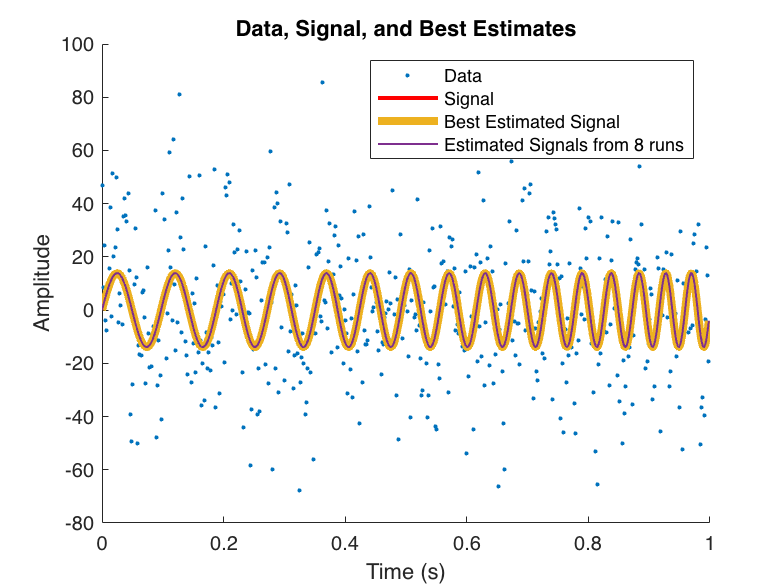




figure
hold on
scatter(timeVec,dataVec,'Marker','.');
plot(timeVec,sigVec,'Color','Red','LineWidth',2.0);
plot(timeVec,outStruct.bestSig,'LineStyle','-','LineWidth',4.0)

for lpruns = 1:nruns
    plot(timeVec,outStruct.allRunsOutput(lpruns).estSig,'LineWidth',1.0);
end
hold off
legend('Data','Signal','Best Estimated Signal',...
                      ['Estimated Signals from ',num2str(nruns),' runs']);
title('Data, Signal, and Best Estimates');
ylabel('Amplitude');
xlabel('Time (s)');

disp(['Estimated parameters: a1=',num2str(outStruct.bestQcCoefs(1)),...
                          '; a2=',num2str(outStruct.bestQcCoefs(2)),...
                          '; a3=',num2str(outStruct.bestQcCoefs(3))]);

Estimated parameters: a1=9.9631; a2=3.1282; a3=2.9106
